# **2 - INTEREST RATES BOOTSTRAP**

## **EXERCISE 1: **Bootstrap for Euribor 3M Interbank curve

Considering the inter-bank market on the 15th of February 2008 at 10:45 C.E.T. Implement the code necessary to realize the bootstrap for the Discount Factors' curve (with a single-curve model). Output values should be on settlement date and expires of quoted underlings. Hints: include in the datesSet of the bootstrap only end dates of underlying contracts.

### **SETUP**

clc; clear; close all;
addpath(genpath(fullfile('..', '..', 'lib')));
InitializeProject();

### **UPLOAD DATA**

filename = fullfile(pathDataRaw, 'MktData_CurveBootstrap');
dateFormat = 'dd/MM/yyyy';
[datesSet, ratesSet] = ReadExcelData(filename, dateFormat);

### **BOOTSTRAP DISCOUNT AND ZERO RATES**

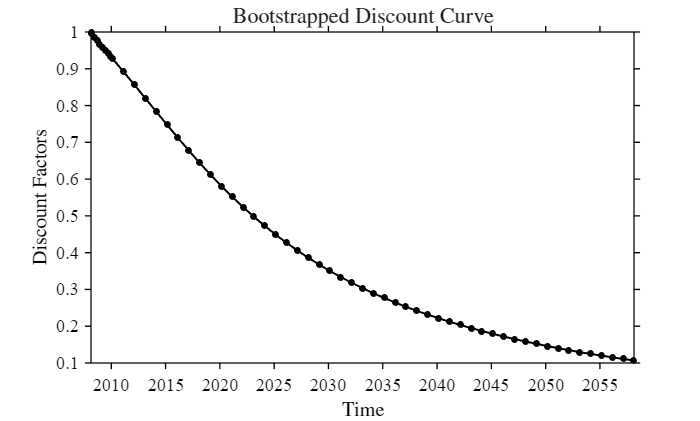

[dates, discounts] = Bootstrap(datesSet, ratesSet);
zeroRates = ZeroRates(dates, discounts);

figDISC = figure;
plot(dates, discounts, '-o', 'DisplayName', 'Bootstrapped Discount'); hold on;
PlotUtils.setStyle();
PlotUtils.setLabels('Time', 'Discount Factors', ...
    'Bootstrapped Discount Curve');

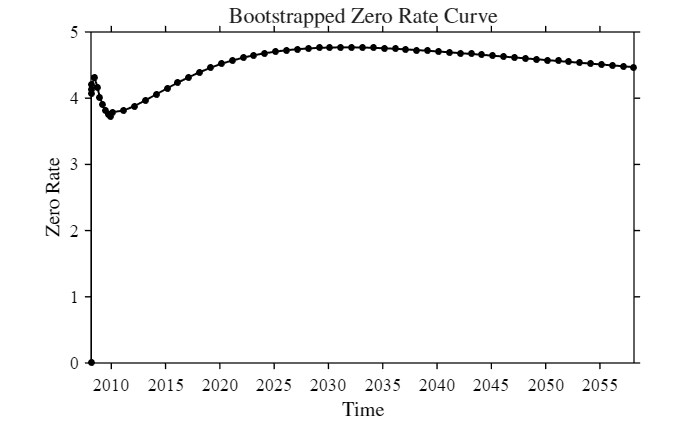

figZRATES = figure;
plot(dates, 100 * zeroRates, '-o', 'DisplayName', 'Bootstrapped Zero Rates');
PlotUtils.setStyle();
PlotUtils.setLabels('Time', 'Zero Rate', ...
    'Bootstrapped Zero Rate Curve');

## **EXERCISE 2: Sensitivities for an IRS**

With the discount curve obtained above compute the absolute value of the quantities specified below for a portfolio composed only by one single swap. A 6y plain vanilla IR swap vs Eurbibor 3m with a fixed rate 2.817% and a Notional of €10 Mln:

- DV01-parallel shift;

- DV01(z)-parallel shift;

- BPV of the 5y IRS;

For "I.B. coupon bond" with same expiry, fixed rate & reset dates of the IRS, and face value equal to IRS Notional:

- its Macaulay Duration.

### **SETUP**

clc; clear; close all;
addpath(genpath(fullfile('..', '..', 'lib')));
InitializeProject();

### **UPLOAD DATA**

BootstrapCurves = load(fullfile(pathLib, 'BootstrapCurves.mat'));
dates = BootstrapCurves.dates;
discounts = BootstrapCurves.discounts;
zeroRatesShift = ZeroRates(dates, discounts) + 1e-4;
discounts_DV01 = Discounts(dates, zeroRatesShift);

SwapData = load(fullfile(pathDataRaw, 'SwapData.mat'));
setDate = SwapData.SettlementDate;
fixedLegPaymentDates = SwapData.FixedLegDates;
fixedRate = SwapData.FixedRate;

### **COMPUTE SENSITIVITIES**

[DV01, BPV, DV01_z] = SensSwap(setDate, fixedLegPaymentDates, fixedRate, dates, discounts, discounts_DV01);
MacD = SensCouponBond(setDate, fixedLegPaymentDates, fixedRate, dates, discounts);
T = table(DV01 * 1e4, DV01_z * 1e4, BPV * 1e4, MacD, 'VariableNames', {'DV01', 'DV01 Zero Rates', 'BPV', 'Maculay Duration'}, 'RowNames', {'Sensitivities (bps)'});
display(T)

T = 1×4 table
                            DV01     DV01 Zero Rates     BPV      Maculay Duration
                           ______    _______________    ______    ________________

    Sensitivities (bps)    5.2049        5.2049         5.2399         5.3728     
